# Actividad Integradora del Bloque F1013B

## Potencial eléctrico y Campo eléctrico de un dipolo

## Juan Sebastian Gonzalez A01644942

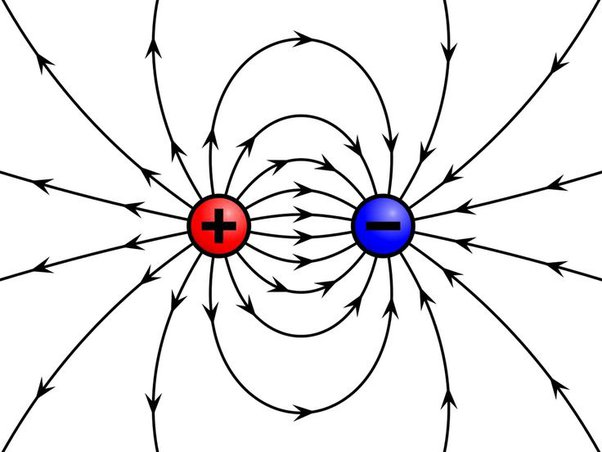

### Potencial eléctrico para una carga puntual:


$$V=k_e \frac{q}{r}$$


donde       $r=\sqrt{{r_x }^2 +{r_y }^2 }=\sqrt{\left({\left(x-x_o \right)}^2 +{\left(y-y_o \right)}^2 \right)}$

y      ($x_o$,$y_o$) es la posición de la carga puntual

### Campo eléctrico para una carga puntual:


$$\vec{\mathit{\mathbf{E}}} =-\nabla V$$


donde   $\nabla V=\frac{\partial V}{\partial x}\hat{\mathit{\mathbf{i}}} +\frac{\partial V}{\partial y}\hat{\mathit{\mathbf{j}}}$ es el gradiente del potencial eléctrico

Comandos generales de limpieza:

clear
close all
clc

Creación de la malla:

m = 2;
dm = .1; 

x = -m:dm:m;
y = -m:dm:m;

[xx,yy] = meshgrid(x, y);  %Coordenadas cartesianas de cada punto de la malla 

Posición de las Cargas:

%Posición de la carga positiva
xp= -.5; yp=  0;

%Posición de la carga negativa
xn=  .5;  yn=  0; 

Valor de las Cargas en microColoumbs 

Qp = 1e-6;  %carga positiva

Qn = -1e-6; %carga negativa

eps0 = 8.854e-12; %Permitividad del vacío
k = 1/(4*pi*eps0); %Constante de Coulomb


Potencial eléctrico del dipolo en cada punto del plano:

%Potencial eléctrico debido a la Carga positiva
r = 1e-9; %Radio ficticio de la carga para evitar la división entre cero
rxp = xx - xp;
ryp = yy - yp;
rp = sqrt(rxp.^2 + ryp.^2 + r.^2);

Vp = k.*Qp./rp;
 

%Potencial eléctrico debido a la Carga negativa
rxn = xx - xn;
ryn = yy - yn;
rn = sqrt(rxn.^2 + ryn.^2 + r.^2);

Vn = k.*Qn./rn;

%Potencial eléctrico total debido al dipolo
Vtotal = Vp + Vn;

Visualización del Potencial eléctrico de un dipolo:

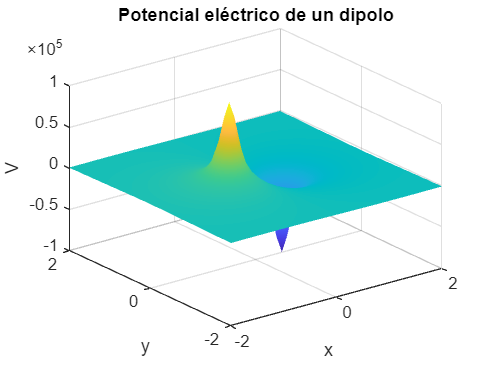

figure

graphedVTotal = Vtotal;
graphedVTotal(Vtotal > 1e5) = 1e5;
graphedVTotal(Vtotal < -1e5) = -1e5;
surf(xx, yy , graphedVTotal); shading interp; colormap parula;

title('Potencial eléctrico de un dipolo')
xlabel('x'); ylabel('y'); zlabel('V')

Campo eléctrico del dipolo en cada punto del plano:

[fx,fy]= gradient(Vtotal);    %Gradiente del potencial eléctrico


%Componentes vectoriales del Campo eléctrico
Ex = -fx;
Ey = -fy;


Normalización del Campo eléctrico en cada punto del plano (Magnitud del Campo eléctrico = 1):


$$\left|\hat{\mathit{\mathbf{E}}} \right|=1$$



$$\hat{\mathit{\mathbf{E}}} =\frac{\vec{\mathit{\mathbf{E}}} }{|E|}=\frac{E_x \hat{\mathit{\mathbf{i}}} +E_y \hat{\mathit{\mathbf{j}}} }{\sqrt{{E_x }^2 +{E_y }^2 }}=\frac{E_x }{\sqrt{{E_x }^2 +{E_y }^2 }}\hat{\mathit{\mathbf{i}}} +\frac{E_y }{\sqrt{{E_x }^2 +{E_y }^2 }}\hat{\mathit{\mathbf{j}}}$$


% Magnitud del Campo eléctrico en cada punto del plano
E = sqrt(Ex.^2 + Ey.^2); 

%Componentes "Ex" y "Ey" del Campo eléctrico normalizadas
Ex_norm = Ex./E;
Ey_norm = Ey./E;

Visualización del Campo eléctrico  de un dipolo:

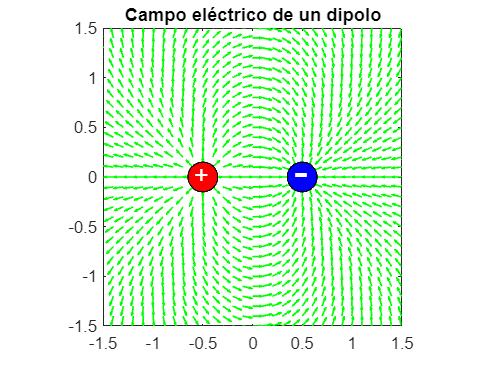

figure 
h=quiver(xx, yy, Ex_norm, Ey_norm);    %Visualización del Campo eléctrico de un dipolo
set(h,'color','g','LineWidth',1,'AutoScaleFactor',0.7); %Características de las flechas

hold on

%Visualización de las cargas
a=0.3; %radio de la carga

%Carga positiva
h=rectangle('Position',[xp-a/2,yp-a/2,a,a],'curvature',[1 1]); 
set(h,'Facecolor','r','Edgecolor','k'); 
text(xp-a/3.2,yp+a/14,'+','Color','white','FontSize',15);

%Carga negativa

h=rectangle('Position',[xn-a/2,yn-a/2,a,a],'curvature',[1 1]); 
set(h,'Facecolor','b','Edgecolor','k'); 
text(xn-a/3.5,yn+a/4.2,'-','Color','white','FontSize',25); 

title('Campo eléctrico de un dipolo')
axis equal
xlim([-1.5, 1.5]), ylim([-1.5, 1.5])

hold off

Visualización de las líneas de Campo eléctrico  y Curvas equipotenciales de un dipolo

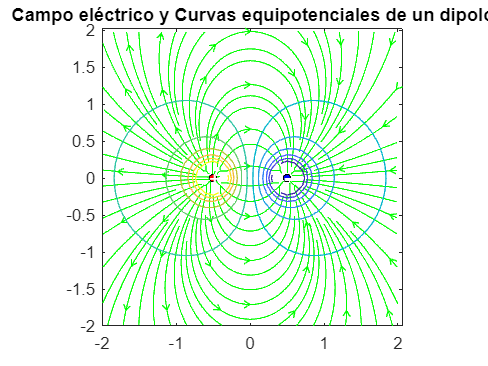

figure
h = streamslice(xx, yy, Ex, Ey); %Líneas de Campo eléctrico
set(h,'color','g','LineWidth',0.5); 

hold on

graphedVTotal = Vtotal;
graphedVTotal((Vtotal < -10^4.7) | (Vtotal > 10^4.7)) = NaN;
contour(xx, yy, graphedVTotal, 12); colormap parula   %Curvas equipotenciales

%Visualización de las cargas
a=0.1; %radio de la carga

%Carga positiva
h=rectangle('Position',[xp-a/2,yp-a/2,a,a],'curvature',[1 1]); 
set(h,'Facecolor','r','Edgecolor','k'); 
text(xp-0.05,yp,'+','Color','white','FontSize',12);

%Carga negativa

h=rectangle('Position',[xn-a/2,yn-a/2,a,a],'curvature',[1 1]); 
set(h,'Facecolor','b','Edgecolor','k'); 
text(xn-0.04,yn+0.04,'-','Color','white','FontSize',20); 

title('Campo eléctrico y Curvas equipotenciales de un dipolo')
box on
axis equal
axis tight

hold off

## Comentarios Finales

En el curso, pude explorar un amplio espectro de aplicaciones de este software. Pude apreciar la importancia de relacionar la computacion con la fisica, y los beneficios que puede proveer, al llevar a cabo experimentos virtuales y modelar fenómenos electricos o fisicos en general. Aprendi a visualizar las ecuaciones y conceptos fisicos por medio del computo, y a relacionar los problemas analiticos con soluciones numericas, para llegar a aproximaciones de estos.